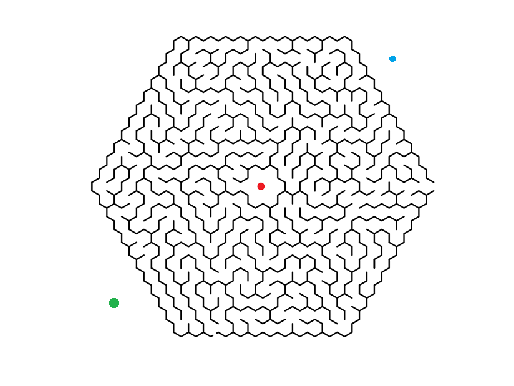

A = imread("Laberint.png");
G = rgb2gray(A);
imshow(A);

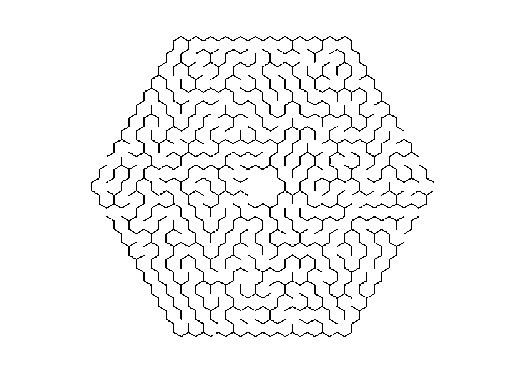

SE = [1 1 1; 1 1 1; 1 1 1];
%GREEN = [0, 0.5, 0.35] [0, 127.5, 89.25] APROXIMADAMENTE
%BLUE = [0.3010, 0.6314, 0.9330] [76.75, 161, 237.915] APROXIMADAMENTE
%RED = [1,0,0] [255,0,0] APROXIMADAMENTE
GREEN = A(:,:,1) < 50 & A(:,:,2) > 100 & A(:,:,3) < 80;
BLUE = A(:,:,1) < 100 & A(:,:,2) < 200 & A(:,:,3) > 200;
RED = A(:,:,1) > 200 & A(:,:,2) < 50 & A(:,:,3) < 50;
BIN = G>50;
imshow(BIN);

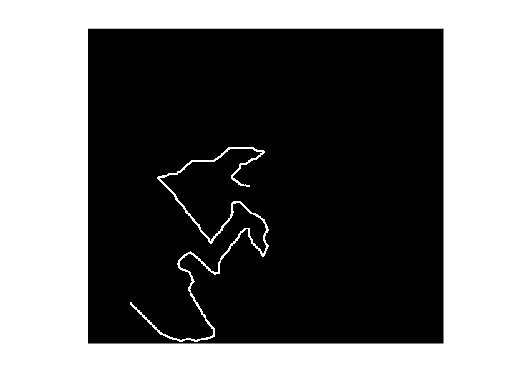

[GREEN_PIXELS, N_GREEN] = pixelPath(GREEN,RED,SE,BIN);
[GREEN_INVERSE_PIXELS, IDEM] = pixelPath(RED,GREEN,SE,BIN);
[BLUE_PIXELS, N_BLUE] = pixelPath(BLUE,RED,SE,BIN);
[BLUE_INVERSE_PIXELS, IDEM2] = pixelPath(RED,BLUE,SE,BIN);
GREEN_TOTAL = representation(GREEN_PIXELS,GREEN_INVERSE_PIXELS,N_GREEN);

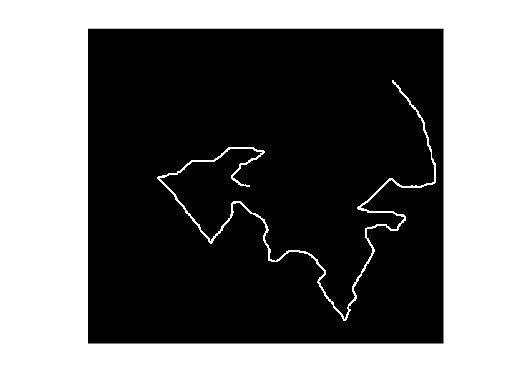

BLUE_TOTAL = representation(BLUE_PIXELS,BLUE_INVERSE_PIXELS,N_BLUE);

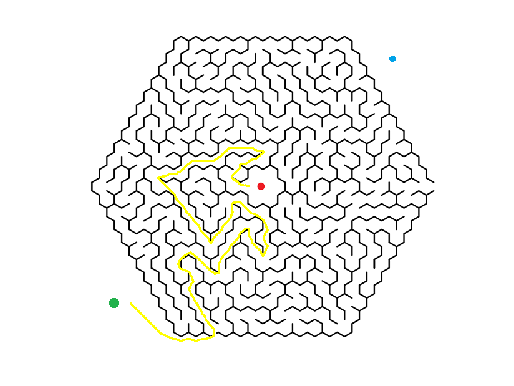

GREEN_END = imoverlay(A,GREEN_TOTAL,'yellow');
BLUE_END = imoverlay(A,BLUE_TOTAL,'yellow');
imshow(GREEN_END);

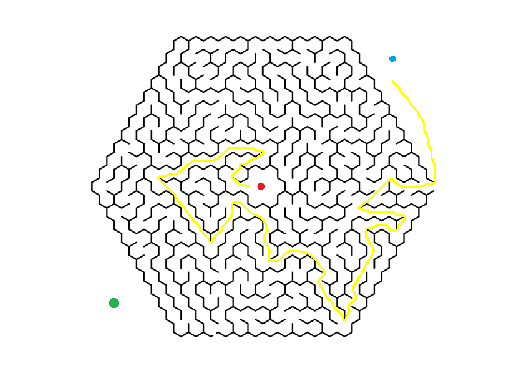

imshow(BLUE_END);

function [Dist_Mat,Pixels] = pixelPath(color_ini,color_end,expansion_shape,BIN)
    Aux = color_ini;
    Dist_Mat = im2double(color_ini);
    Pixels = 1;
    while sum(sum(Aux&color_end)) == 0
        Pixels = Pixels + 1;
        Before = Aux;
        Aux = imdilate(Aux,expansion_shape);
        Aux = Aux&BIN;
        Painted = Aux - Before;
        Dist_Mat = Dist_Mat + Painted*Pixels;
    end 
end

function Dist_total = representation(Color_Pixels,Inverser_Color_Pixels, N)
    SE = [1 1 1; 1 1 1; 1 1 1];    
    Dist_total = Color_Pixels + Inverser_Color_Pixels;
    Dist_total = Dist_total == N+1;
    imshow(Dist_total);
    Dist_total = bwskel(Dist_total);
    Dist_total = imdilate(Dist_total,SE);
    imshow(Dist_total);
end